part 1 section 1

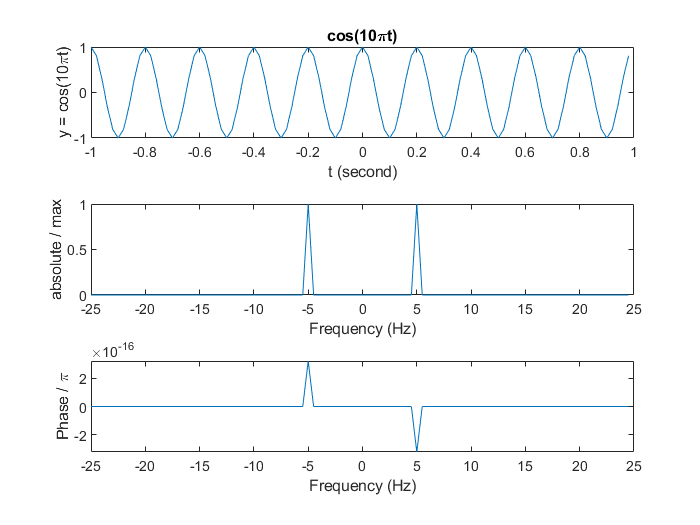

tstart = -1;
tend = 1;
fs = 50;
ts = 1/fs;

t = tstart:ts:tend-ts;
N = length(t);
x = cos(10*pi*t);
subplot(3, 1, 1);
plot(t, x)
title("cos(10\pit)");
xlabel('t (second)');
ylabel('y = cos(10\pit)');

xf = fftshift(fft(x));
xf = xf/max(abs(xf));
fr = -fs/2:fs/N:fs/2-fs/N;

subplot(3, 1, 2);
plot(fr, abs(xf));
xlabel('Frequency (Hz)');
ylabel('absolute / max');

subplot(3, 1, 3);
tol = 1e-6;
xf(abs(xf) < tol) = 0;
plot(fr, angle(xf));
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

part 2

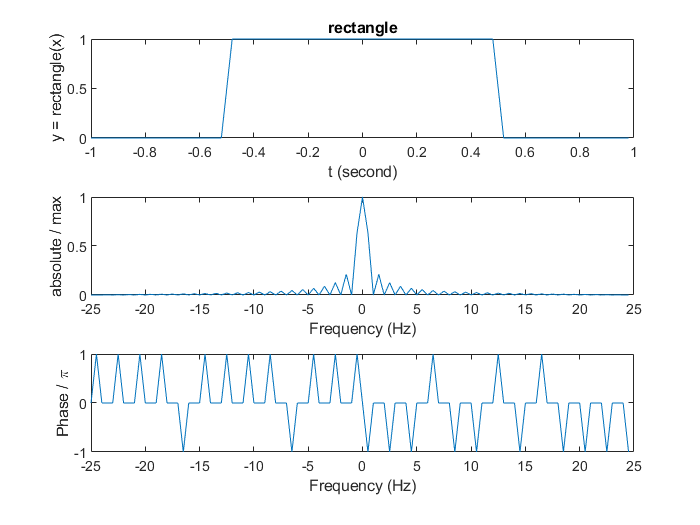

tstart = -1;
tend = 1;
fs = 50;
ts = 1/fs;

t = tstart:ts:tend-ts;
N = length(t);
x = rectangularPulse(t);
subplot(3, 1, 1)
plot(t, x)
title("rectangle");
xlabel('t (second)');
ylabel('y = rectangle(x)');

xf = fftshift(fft(x));
xf = xf/max(abs(xf));
fr = -fs/2:fs/N:fs/2-fs/N;

subplot(3, 1, 2)
plot(fr, abs(xf))
xlabel('Frequency (Hz)')
ylabel('absolute / max')

subplot(3, 1, 3)
tol = 1e-6;
xf(abs(xf) < tol) = 0;
plot(fr, angle(xf)/pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

part 3

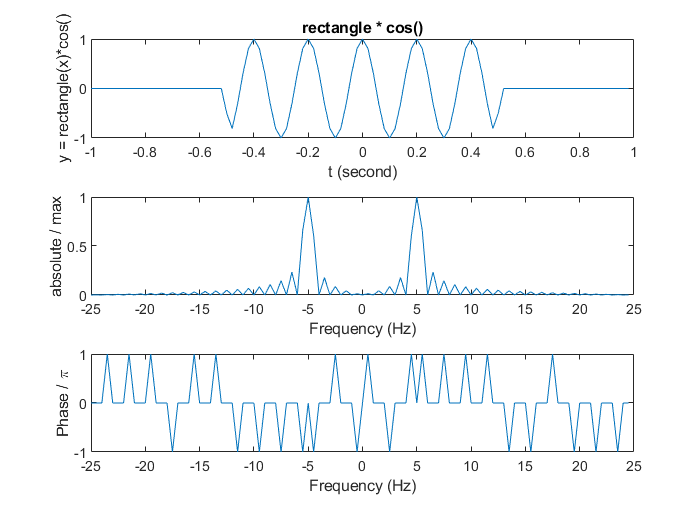

tstart = -1;
tend = 1;
fs = 50;
ts = 1/fs;

t = tstart:ts:tend-ts;
N = length(t);
y = cos(10*pi*t);
z = rectangularPulse(t);
x = z.*y;
subplot(3, 1, 1)
plot(t, x)
title("rectangle * cos()");
xlabel('t (second)');
ylabel('y = rectangle(x)*cos()');

xf = fftshift(fft(x));
xf = xf/max(abs(xf));
fr = -fs/2:fs/N:fs/2-fs/N;

subplot(3, 1, 2)
plot(fr, abs(xf))
xlabel('Frequency (Hz)')
ylabel('absolute / max')

subplot(3, 1, 3)
tol = 1e-6;
xf(abs(xf) < tol) = 0;
plot(fr, angle(xf)/pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

part 4

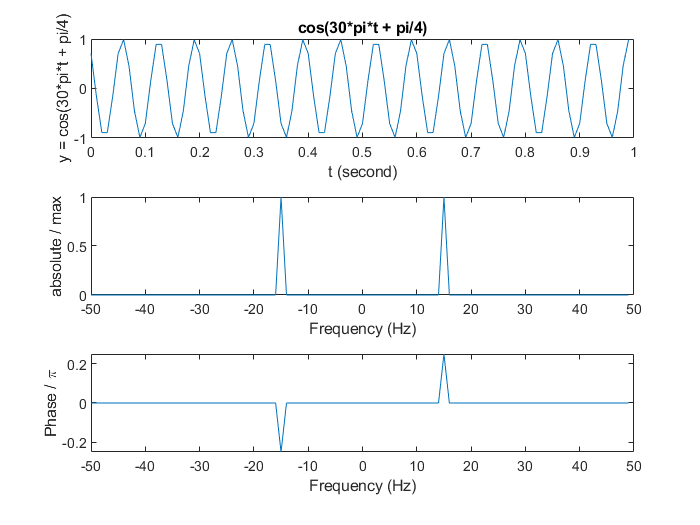

tstart = 0;
tend = 1;
fs = 100;
ts = 1/fs;

t = tstart:ts:tend-ts;
N = length(t);
x = cos(30*pi*t + pi/4);

subplot(3, 1, 1)
plot(t, x)
title('cos(30*pi*t + pi/4)');
xlabel('t (second)');
ylabel('y = cos(30*pi*t + pi/4)');

xf = fftshift(fft(x));
xf = xf/max(abs(xf));
fr = -fs/2:fs/N:fs/2-fs/N;

subplot(3, 1, 2)
plot(fr, abs(xf))
xlabel('Frequency (Hz)')
ylabel('absolute / max')

subplot(3, 1, 3)
tol = 1e-6;
xf(abs(xf) < tol) = 0;
plot(fr, angle(xf)/pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

part 5

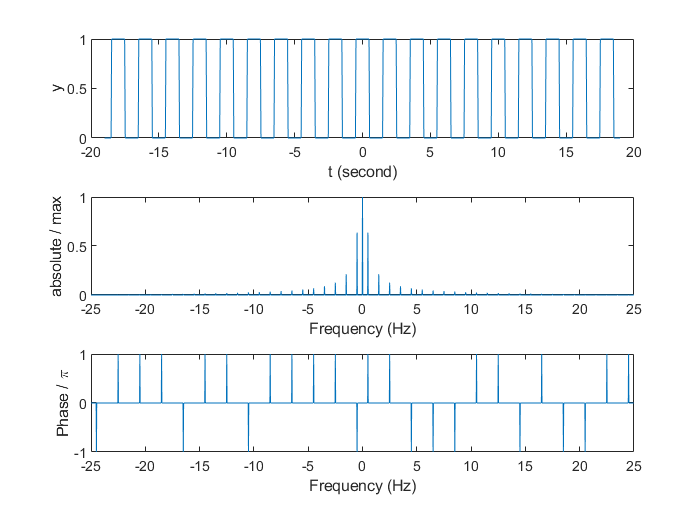

tstart = -19;
tend = 19;
fs = 50;
ts = 1/fs;

t = tstart:ts:tend-ts;
N = length(t);

x = zeros(1, 1900);

for w = -9:9
    x = x + rectangularPulse(-1/2 - 2*w, 1/2 - 2*w, t);
end

subplot(3, 1, 1)
plot(t, x)
xlabel('t (second)');
ylabel('y');

xf = fftshift(fft(x));
xf = xf/max(abs(xf));
fr = -fs/2:fs/N:fs/2-fs/N;

subplot(3, 1, 2)
plot(fr, abs(xf))
xlabel('Frequency (Hz)')
ylabel('absolute / max')

subplot(3, 1, 3)
tol = 1e-6;
xf(abs(xf) < tol) = 0;
plot(fr, angle(xf)/pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

section 2

part 1

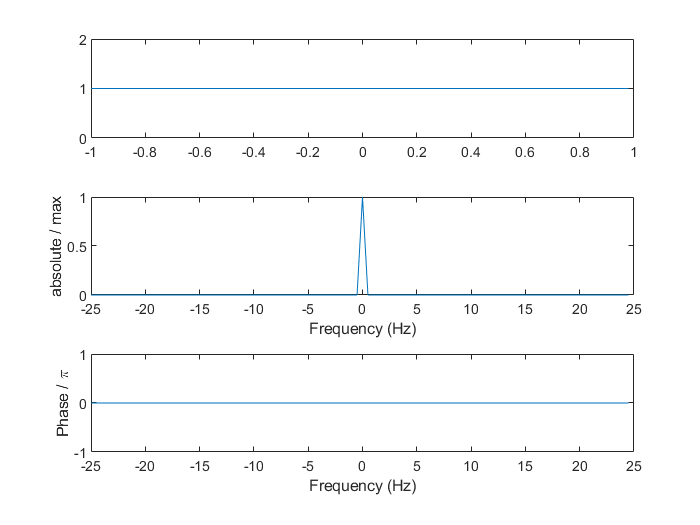

tstart = -1;
tend = 1;
fs = 50;
ts = 1/fs;

t = tstart:ts:tend-ts;
N = length(t);

subplot(3, 1, 1)
x = ones(1,100);
plot(t, x)
xlabel('t (second)');
ylabel('y');

plot(t, x)

xf = fftshift(fft(x));
xf = xf/max(abs(xf));
fr = -fs/2:fs/N:fs/2-fs/N;

subplot(3, 1, 2)
plot(fr, abs(xf))
xlabel('Frequency (Hz)')
ylabel('absolute / max')

subplot(3, 1, 3)
tol = 1e-6;
xf(abs(xf) < tol) = 0;
plot(fr, angle(xf))
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

part 2

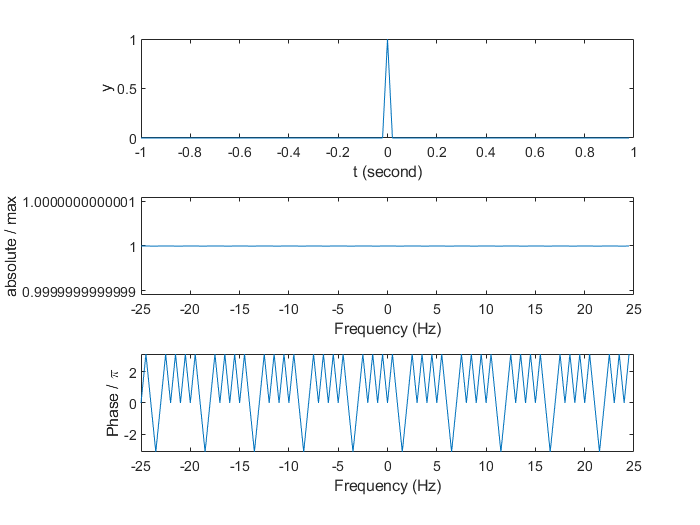

tstart = -1;
tend = 1;
fs = 50;
ts = 1/fs;

t = tstart:ts:tend-ts;
N = length(t);

x = zeros(1, 100);
x(51) = 1;

subplot(3, 1, 1)
plot(t, x)
xlabel('t (second)');
ylabel('y');

xf = fftshift(fft(x));
xf = xf/max(abs(xf));
fr = -fs/2:fs/N:fs/2-fs/N;

subplot(3, 1, 2)
plot(fr, abs(xf))
xlabel('Frequency (Hz)')
ylabel('absolute / max')

subplot(3, 1, 3)
tol = 1e-6;
xf(abs(xf) < tol) = 0;
plot(fr, angle(xf))
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

section 3

 part 1

syms t
x = exp(-t^2/8);
fun = fourier(x)

$$fun = 2\,\sqrt{2}\,\sqrt{\pi }\,{\mathrm{e}}^{-2\,w^{2}}$$

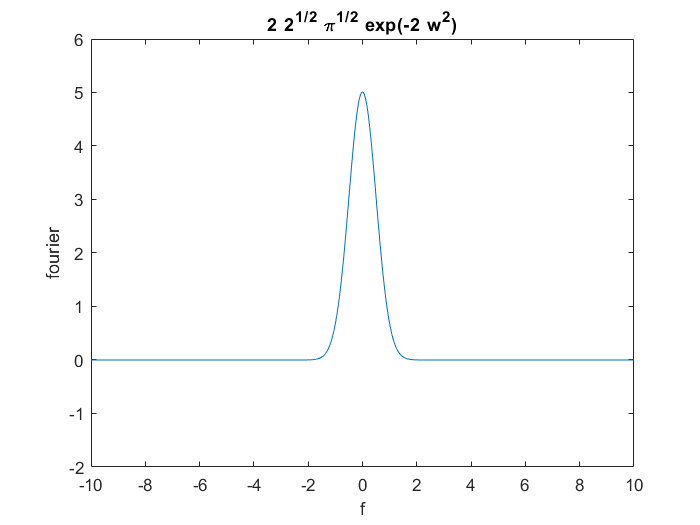

subplot(1, 1, 1)
ezplot(fun, [-10, 10])
ylim([-2 6])
xlabel('f')
ylabel('fourier')

section 3 

part 2

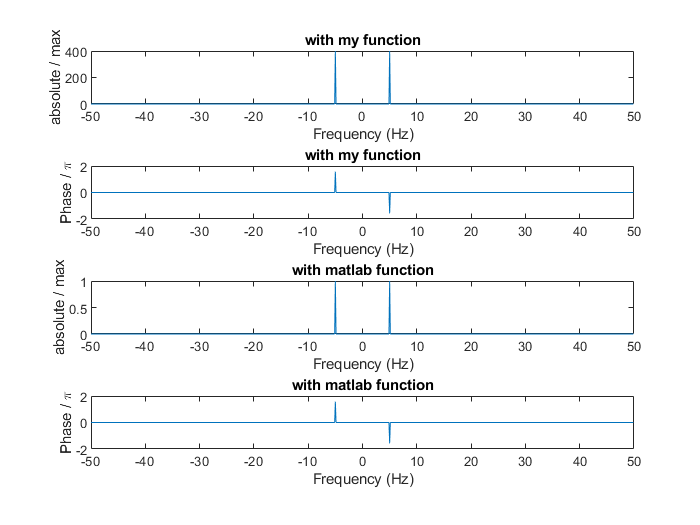

clc
clear all

tstart = 0;
tend = 8;
fs = 100;
ts = 1/fs;

t = tstart:ts:tend-ts;
N = length(t);

freq = -fs/2:fs/N:fs/2-fs/N;
X = zeros(1, length(freq));

for fr = 1:length(freq)
    for tf = 1:length(t)
          X(fr) = X(fr) + sin(10*pi*(t(tf)))*exp((-1i)*2*pi*t(tf)*freq(fr));
    end
end

subplot(4, 1, 1)
plot(freq, abs(X))
title("with my function")
xlabel('Frequency (Hz)')
ylabel('absolute / max')

subplot(4, 1, 2)
tol = 1e-6;
X(abs(X) < tol) = 0;
plot(freq, angle(X))
title("with my function")
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')


xf = fftshift(fft(sin(10*pi*t)));
xf = xf/max(abs(xf));

subplot(4, 1, 3)
plot(freq, abs(xf))
title("with matlab function")
xlabel('Frequency (Hz)')
ylabel('absolute / max')

subplot(4, 1, 4)
tol = 1e-6;
xf(abs(xf) < tol) = 0;
plot(freq, angle(xf))
title("with matlab function")
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')